# **Κεφάλαιο 3: Μετασχηματισμοί Δεδομένων**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, έχουν προσαρμοστεί από παραδείγματα που βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## Ανάλυση σε Κύριες Συνιστώσες

### Παράδειγμα 1

1. Δημιουργήστε ένα σύνολο $X_1$ που αποτελείται από $N=500$ διδιάστατα διανύσματα που ακολουθούν Gaussian κατανομή μηδενικής μέσης τιμής και μητρώου συνδιασποράς


$$S_1=\left[ \matrix {0.3 & 0.2 \cr 0.2 & 1.0}
\right]$$


close('all');
clear;

% 1. Generate the data set X1
randn('seed',0) ;
S1=[.3 .2; .2 1];
[l,l]=size(S1);
mv=zeros(1,l);
N=500;
m=2;
X1=mvnrnd(mv,S1,N)';


Εφαρμόστε PCA στο $X_1$, δηλαδή υπολογίστε τις ιδιοτιμές / ιδιοδιανύσματα της εκτίμησης $\hat{S_1}$ του $S_1$, η οποία προκύπτει από τα διανύσματα του $X_1$. Λαμβάνοντας υπόψιν ότι η $i-$οστή ιδιοτιμή "εξηγεί" τη διασπορά στην διεύθυνση του $i-$οστού ιδιοδιανύσματος του $\hat{S_1}$, υπολογίστε το ποσοστό της διασποράς που οφείλεται σε κάθε μια συνιστώσα, ως τον λόγο $\frac{ \lambda_i}{\lambda_0 + \lambda_1}, i=0,1$. Σχεδιάστε το σύνολο δεδομένων $X_1$ και τα ιδιοδιανύσματα του $\hat{S_1}$ και σχολιάστε τα αποτελέσματα.

% Apply PCA on X1 and compute the percentage of the total variance explained by each component
[eigenval,eigenvec,explained,Y,mean_vec]=pca_fun(X1,m);
eigenval

eigenval =     1.0408
    0.2769


eigenvec

eigenvec =     0.1925   -0.9813
    0.9813    0.1925


explained

explained =     0.7898
    0.2102


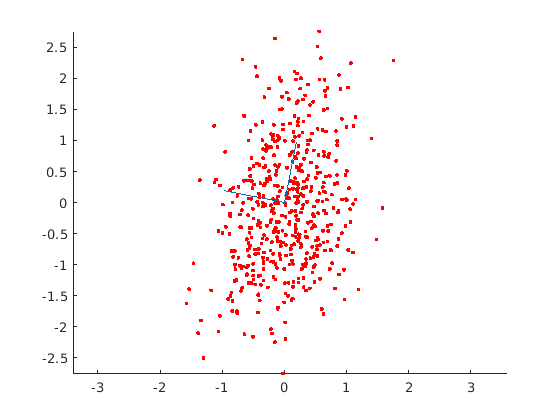


% Plot the data points and the normalized eigenvectors
figure(1), hold on
figure(1), plot(X1(1,:),X1(2,:),'r.')
figure(1), axis equal
figure(1), line([0; eigenvec(1,1)],[0; eigenvec(2,1)])
figure(1), line([0; eigenvec(1,2)],[0; eigenvec(2,2)])

2. Δημιουργήστε όπως προηγουμένως ένα σύνολο δεδομένων $X_2$, όπου αυτή τη φορά ο πίνακας συνδιασποράς είναι $S_1=\left[ \matrix {0.3 & 0.2 \cr 0.2 & 9.0}
\right]$. Στη συνέχεια επαναλάβετε το προηγούμενο πείραμα.

% 2. Generate the data set X2
randn('seed',0) ;
S2=[.3 .2; .2 9];
[l,l]=size(S2);
mv=zeros(1,l);
N=500;
m=2;
X2=mvnrnd(mv,S2,N)';

% Apply PCA on X2 and compute the percentage of the total variance explained by each component
[eigenval,eigenvec,explained,Y,mean_vec]=pca_fun(X2,m);
eigenval

eigenval =     9.6614
    0.3052


eigenvec

eigenvec =     0.0015   -1.0000
    1.0000    0.0015


explained

explained =     0.9694
    0.0306


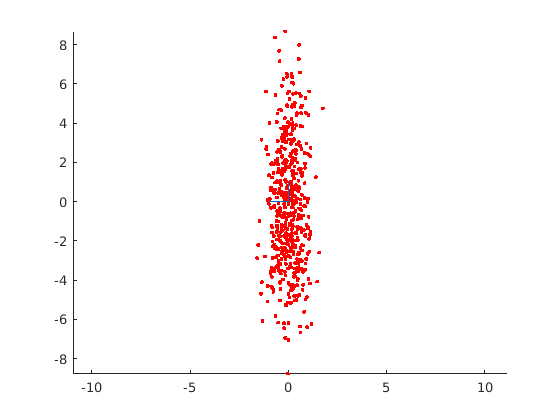


% Plot the data points and the normalized eigenvectors
figure(2), hold on
figure(2), plot(X2(1,:),X2(2,:),'r.')
figure(2), axis equal
figure(2), line([0; eigenvec(1,1)],[0; eigenvec(2,1)])
figure(2), line([0; eigenvec(1,2)],[0; eigenvec(2,2)])

### Παράδειγμα 2

1. α) Δημιουργήστε ένα σύνολο $X_1$ που αποτελείται από $N=400$ διδιάστατα διανύσματα που προέρχονται από δύο κλάσεις. Το πρώτο μισό του συνόλου ανήκει στην πρώτη κλάση, η οποία μοντελοποιείται με Gaussian κατανομή μέσης τιμής $m_1=[-8,8]^T$, ενώ το υπόλοιπο του συνόλου πηγάζει από τη δεύτερη κλάση, Gaussian κατανομής και μέσης τιμής $m_2=[8,8]^T$. Το μητρώο συνδιασποράς 


$$S_1=\left[ \matrix {0.3 & 1.5 \cr 1.5 & 1.0}
\right]$$


είναι κοινό και για τις δύο κλάσεις.

close('all');
clear;

% 1(a). To generate the data set X1 and a vector y1, whose i-th coordinate
% contains the class label of the i-th vector of X1, type
randn('seed',0)  
S=[.3 1.5; 1.5 9];
[l,l]=size(S);
mv=[-8 8; 8 8]';
N=200;
X1=[mvnrnd(mv(:,1),S,N); mvnrnd(mv(:,2),S,N)]';
y1=[ones(1,N), 2*ones(1,N)];


β) Εφαρμόστε PCA στο $X_1$ και υπολογίστε το ποσοστό της συνολικής διασποράς που "εξηγεί" κάθε συνιστώσα.

% 1(b). To compute the eigenvalues/eigenvectors and variance percentages required in this step type
m=2;
[eigenval,eigenvec,explained,Y,mean_vec]=pca_fun(X1,m);
eigenval
eigenvec
explained


γ) Να γίνει προβολή των διανυσμάτων του $X_1$ στη διεύθυνση της πρώτης κύριας συνιστώσας και να σχεδιαστεί το σύνολο των δεδομένων $X_1$ καθώς και η προβολή του ως προς την πρώτη κύρια συνιστώσα. Σχολιάστε τα αποτελέσματα.

% 1(c). The projections of the data points of X1 along the direction of the first
% principal component are contained in the first row of Y , returned by the
% function pca_fun above. 

% Plot X1

eigenval =    64.2398
    9.3085


figure(1), hold on

eigenvec =    -1.0000    0.0089
   -0.0089   -1.0000


figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==2),X1(2,y1==2),'bo')

explained =     0.8734
    0.1266



% Compute the projections of X1
w=eigenvec(:,1);
t1=w'*X1(:,y1==1);
t2=w'*X1(:,y1==2);
X_proj1=[t1;t1].*((w/(w'*w))*ones(1,length(t1)));
X_proj2=[t2;t2].*((w/(w'*w))*ones(1,length(t2)));

% Plot the projections
figure(1), plot(X_proj1(1,:),X_proj1(2,:),'k.',X_proj2(1,:),X_proj2(2,:),'ko')
figure(1), axis equal

% Plot the eigenvectors
figure(1), line([0; eigenvec(1,1)], [0; eigenvec(2,1)])
figure(1), line([0; eigenvec(1,2)], [0; eigenvec(2,2)])


2. Να επαναληφθεί το βήμα 1 για το σύνολο $X_2$ , που δημιουργείται όπως το $X_1$, αλλά με $m_1=[-1,0]^T$ και  $m_2=[1,0]^T$.

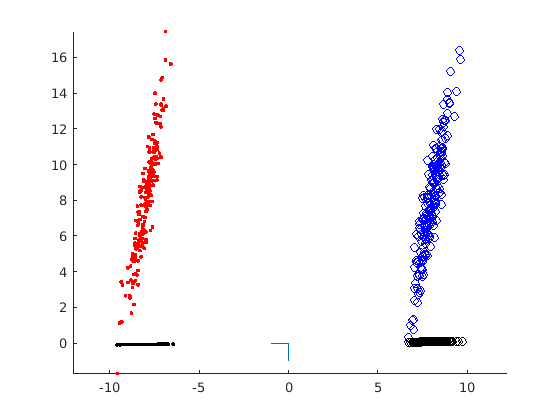

% 2(a). To generate X2, the code for X1 is executed again where now m1 = [-1, 0]' and m2 = [1, 0]'
randn('seed',0)  
S=[.3 1.5; 1.5 9];
[l,l]=size(S);
mv=[-1 0; 1 0]';
N=200;
X1=[mvnrnd(mv(:,1),S,N); mvnrnd(mv(:,2),S,N)]';
y1=[ones(1,N), 2*ones(1,N)];

% 2(b). Compute the eigenvalues/eigenvectors and variance percentages required in this step

m=2;
[eigenval,eigenvec,explained,Y,mean_vec]=pca_fun(X1,m);
eigenval
eigenvec
explained

% 2(c).
% Plot X1
figure(2), hold on
figure(2), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==2),X1(2,y1==2),'bo')

% Compute the projections of X1
w=eigenvec(:,1);
t1=w'*X1(:,y1==1);
t2=w'*X1(:,y1==2);
X_proj1=[t1;t1].*((w/(w'*w))*ones(1,length(t1)));

eigenval =     9.5481
    1.0390


X_proj2=[t2;t2].*((w/(w'*w))*ones(1,length(t2)));

eigenvec =     0.1663   -0.9861
    0.9861    0.1663


explained =     0.9019
    0.0981


% Plot the projections
figure(2), plot(X_proj1(1,:),X_proj1(2,:),'k.',X_proj2(1,:),X_proj2(2,:),'ko')
figure(2), axis equal

% Plot the eigenvectors
figure(2), line([0; eigenvec(1,1)], [0; eigenvec(2,1)])
figure(2), line([0; eigenvec(1,2)], [0; eigenvec(2,2)])


3. Να συγκριθούν τα αποτελέσματα των βημάτων 1 και 2 και να εξαχθούν συμπεράσματα.

## Ανάλυση σε ιδιάζουσες τιμές

### Παράδειγμα 1

Δημιουργήστε ένα σύνολο $X_1$ που αποτελείται από $N=100$ διανύσματα διάστασης $l=2000$. Τα διανύσματα πηγάζουν από μια Gaussian κατανομή με μέση τιμή ίση με το $l-$διάστατο μηδενικό διάνυσμα και με διαγώνιο μητρώο συνδιασποράς $S$, με όλα τα μη μηδενικά στοιχεία ίσα με $0.1$ εκτός από τα $S(1,1),S(2,2)$ που είναι ίσα με $10.000$. Εφαρμόστε PCA και SVD σε αυτό το σύνολο δεδομένων και εξάγετε συμπεράσματα.

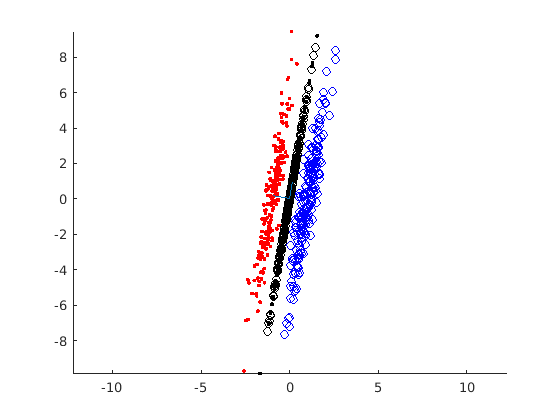

close('all');
clear;

% To generate matrix X, containing the vectors of the data set, type
N=100;
l=2000;
mv=zeros(1,l);
S=0.1*eye(l);
S(1,1)=10000;
S(2,2)=10000;
randn('seed',0)
X=mvnrnd(mv,S,N)';


% To run PCA and SVD on X and to measure the execution time of each method type
% PCA
t0=clock;
m=5;
[eigenval,eigenvec,explain,Y]=pca_fun(X,m);
eigenval
eigenvec
explain

time_PCA=etime(clock,t0)
% SVD
t0=clock;
m=min(N,l);
[U,S,V,Y]=svd_fun(X,m);
time_SVD=etime(clock,t0)

% Uncomment the last line of code to compare the first two columns of eigenvec, produced by PCA,
% with the first two columns of U, produced by SVD, by typing

 [eigenvec(:,1:2) U(:,1:2)]'


## Ανάλυση γραμμικής διάκρισης κατά Fisher

### Παράδειγμα 1

1. Εφαρμόστε ανάλυση Γραμμικής Διάκρισης (LDA) στο σύνολο δεδομένων $X_2$ που δημιουργήθηκε στο δεύτερο μισό του Παραδείγματος 1.

close('all');
clear;

randn('seed',0) 

eigenval = 	1.0e+04 *

    1.1320
    0.9073
    0.0003
    0.0003
    0.0003


S=[.3 1.5; 1.5 9];

eigenvec =    -0.0999    0.9949    0.0001    0.0000   -0.0002
    0.9949    0.0999   -0.0001   -0.0000   -0.0003
    0.0000    0.0001    0.0184   -0.0031    0.0033
    0.0005   -0.0001   -0.0503   -0.0075    0.0343
   -0.0001    0.0004    0.0225    0.0053   -0.0114
   -0.0003   -0.0002   -0.0052   -0.0054   -0.0227
   -0.0002   -0.0004    0.0256    0.0398    0.0074
   -0.0003    0.0002    0.0002   -0.0186    0.0269
    0.0002   -0.0005   -0.0148   -0.0074   -0.0309
   -0.0000   -0.0001    0.0162    0.0142    0.0379


[l,l]=size(S);

explain =     0.5498
    0.4407
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


mv=[-1 1; 0 0]';
N=200;

time_PCA = 1.1038

X=[mvnrnd(mv(:,1),S,N); mvnrnd(mv(:,2),S,N)]';
y=[ones(1,N), 2*ones(1,N)];

% 1. Estimate the mean vectors of each class using the available samples
mv_est(:,1)=mean(X(:,y==1)')';

time_SVD = 0.0309

mv_est(:,2)=mean(X(:,y==2)')';

% Compute the within scatter matrix
[Sw,Sb,Sm]=scatter_mat(X,y);
w=inv(Sw)*(mv_est(:,1)-mv_est(:,2));

ans =    -0.0999    0.9949    0.0000    0.0005   -0.0001   -0.0003   -0.0002   -0.0003    0.0002   -0.0000    0.0003    0.0002   -0.0004   -0.0004   -0.0001   -0.0004   -0.0002   -0.0000   -0.0003    0.0001   -0.0003    0.0003    0.0002    0.0007   -0.0001   -0.0003    0.0001   -0.0003    0.0001   -0.0001   -0.0002    0.0000   -0.0001   -0.0005    0.0000    0.0000   -0.0003   -0.0007    0.0002   -0.0004    0.0002    0.0000    0.0004    0.0002    0.0000   -0.0000   -0.0002    0.0004    0.0000    0.0003
    0.9949    0.0999    0.0001   -0.0001    0.0004   -0.0002   -0.0004    0.0002   -0.0005   -0.0001    0.0005   -0.0009   -0.0004   -0.0004   -0.0001   -0.0001    0.0001    0.0005    0.0000    0.0006    0.0003   -0.0004   -0.0001   -0.0002   -0.0004   -0.0002   -0.0003    0.0000   -0.0002   -0.0003    0.0002    0.0002    0.0001   -0.0001    0.0000   -0.0004    0.0003   -0.0005   -0.0003    0.0004   -0.0005   -0.0001    0.0000   -0.0002   -0.0002   -0.0008   -0.0004   -0.0001    0.0001   

w
% Plot the dataset
figure(1), plot(X(1,y==1),X(2,y==1),'r.',X(1,y==2),X(2,y==2),'bo')
figure(1), axis equal

% Compute the projections
t1=w'*X(:,y==1);
t2=w'*X(:,y==2);
X_proj1=[t1;t1].*((w/(w'*w))*ones(1,length(t1)));
X_proj2=[t2;t2].*((w/(w'*w))*ones(1,length(t2)));
X_proj=[X_proj1 X_proj2];

%Plot the projections
figure(1), hold on
figure(1), plot(X_proj(1,y==1),X_proj(2,y==1),'y.',X_proj(1,y==2),X_proj(2,y==2),'co')

2. Να συγκριθούν τα αποτελέσματα με αυτά που ελήφθησαν από την μέθοδο PCA.

### Παράδειγμα 2

1. α) Δημιουργήστε ένα σύνολο δεδομένων $900$ τρισδιάστατων διανυσμάτων, που προέρχονται από δύο κλάσεις. Τα πρώτα $100$ διανύσματα ακολουθούν μια Gaussian κατανομή μηδενικής μέσης τιμής και μητρώου συνδιασποράς

 
$$S_1=\left[ \matrix {0.5 & 0 & 0 \cr 0 & 0.5 & 0 \cr 0 & 0 & 0.01}
\right]$$


Τα υπόλοιπα $800$ διανύσματα ομαδοποιούνται σε $8$ ομάδες των $100$ διανυσμάτων. Κάθε ομάδα υπακούει σε μια Gaussian κατανομή. Όλες αυτές οι κατανομές έχουν κοινό μητρώο συνδιασποράς το


$$S_1=\left[ \matrix {1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & 0.01}
\right]$$


και οι μέσες τιμές τους είναι:

- 
$$m_1=[\alpha,0,0]^T$$


- 
$$m_2=[\alpha/2,\alpha/2,0]^T$$


- 
$$m_3=[0, \alpha,0]^T$$


- 
$$m_4=[-\alpha/2,\alpha/2,0]^T$$


- 
$$m_5=[-\alpha,0,0]^T$$


- 
$$m_6=[-\alpha/2,-\alpha/2,0]^T$$


- 
$$m_7=[0, -\alpha,0]^T$$


- 
$$m_8=[\alpha/2,-\alpha/2,0]^T$$


όπου $\alpha=6$.

close('all');
clear;

% 1(a). Generate a 3x900 dimensional matrix whose columns are the data vectors
randn('seed',10);
S1=[.5 0 0; 0 .5 0; 0 0 .01];
S2=[1 0 0; 0 1 0; 0 0 .01];
a=6;
mv=[0 0 0; a 0 0; a/2 a/2 0; 0 a 0; -a/2 a/2 0;...
    -a 0 0; -a/2 -a/2 0; 0 -a 0; a/2 -a/2 0]';

w =   -23.4499
    3.9772


N=100;

% Generate the dataset
X=[mvnrnd(mv(:,1),S1,N)];
for i=2:9
    X=[X; mvnrnd(mv(:,i),S2,N)];
end
X=X';
c=2; %No of classes
y=[ones(1,N) 2*ones(1,8*N)]; % class labels

β) Σχεδιάστε το τρισδιάστατο σύνολο δεδομένων και δείτε το από διαφορετικές οπτικές γωνίες, προκειμένου να αποκτήσετε μια αίσθηση του πως απλώνονται τα δεδομένα στον τρισδιάστατο χώρο (με την δυνατότητα τρισδιάστατης περιστροφής που παρέχει το MATLAB).

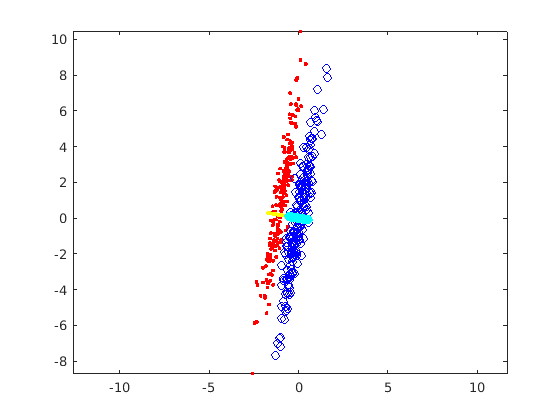

% 1(b). Plot the data set X in the three-dimensional space
figure(1), plot3(X(1,y==1),X(2,y==1),X(3,y==1),'r.',...
    X(1,y==2),X(2,y==2),X(3,y==2),'b.')

figure(1), axis equal

γ) Εφαρμόστε ανάλυση διάκρισης κατά Fisher στο προηγούμενο σύνολο δεδομένων. Να γίνει η προβολή των δεδομένων στον υποχώρο που ορίζουν τα ιδιοδιανύσματα που αντιστοιχούν στις μη-μηδενικές ιδιοτιμές του γινομένου μητρώων $S_w^{-1}S_b$ και να σχολιαστούν τα αποτελέσματα.

% 1(c). 
% Scatter matrix computation
[Sw,Sb,Sm]=scatter_mat(X,y);

% Eigendecomposition
[V,D]=eig(inv(Sw)*Sb);

% Sort the eigenvalues in descending order and rearrange the eigenvectors accordingly
s=diag(D);
[s,ind]=sort(s,1,'descend');
V=V(:,ind);
% Select in A the eigenvectors corresponding to non-zero eigenvalues
A=V(:,1:c-1);
A
% Project the data set on the space spanned by the column vectors of A
Y=A'*X;

% Plot the projections of X
figure(2), plot(Y(y==1),0,'ro',Y(y==2),0,'b.')
figure(2), axis equal

2. Να επαναληφθεί το βήμα 1 για ένα πρόβλημα τριών κλάσεων όπου τα δεδομένα παράγονται όπως στο βήμα 1, με τη διαφορά ότι η τελευταία ομάδα $100$ διανυσμάτων, που ακολουθεί την Gaussian κατανομή μέσης τιμής $m_8$, ανήκει αυτή την φορά στην κλάση $3$.

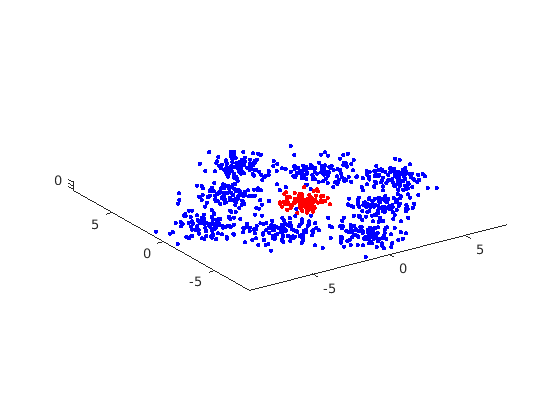

% 2(a).
randn('seed',10)
S1=[.5 0 0; 0 .5 0; 0 0 .01];
S2=[1 0 0; 0 1 0; 0 0 .01];
a=6;
mv=[0 0 0; a 0 0; a/2 a/2 0; 0 a 0; -a/2 a/2 0;...
    -a 0 0; -a/2 -a/2 0; 0 -a 0; a/2 -a/2 0]';
N=100;
% Generate the dataset

X=[mvnrnd(mv(:,1),S1,N)];
for i=2:9
    X=[X; mvnrnd(mv(:,i),S2,N)];
end
X=X';
c=3; % number of classes
y=[ones(1,N) 2*ones(1,7*N) 3*ones(1,N)]; % class labels

% 2(b).
% Plot the dataset X in the three-dimensional space
figure(3), plot3(X(1,y==1),X(2,y==1),X(3,y==1),'r.',X(1,y==2),...
    X(2,y==2),X(3,y==2),'b.',X(1,y==3),X(2,y==3),X(3,y==3),'g.')
figure(3), axis equal

% 2(c).
% Scatter matrix computation
[Sw,Sb,Sm]=scatter_mat(X,y);

A =     0.0162
   -0.2347
   -0.9719


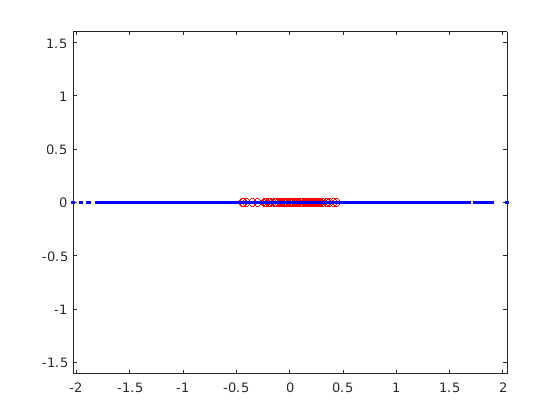


% Eigendecomposition
[V,D]=eig(inv(Sw)*Sb);

% Sort the eigenvalues in descending order and rearrange the eigenvectors accordingly
s=diag(D);

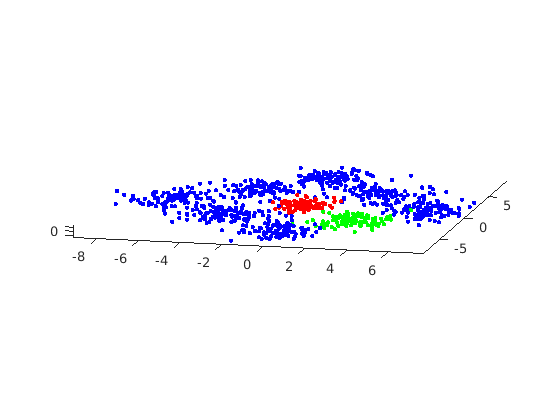

A =    -0.6446    0.1196
    0.6479    0.1209
    0.4059    0.9854


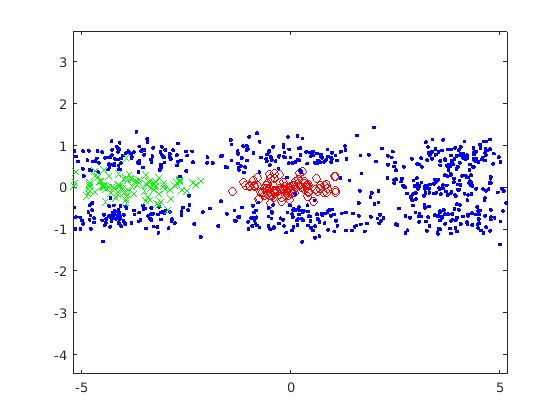

[s,ind]=sort(s,1,'descend');
V=V(:,ind);
% Select in A the eigenvectors corresponding to non-zero eigenvalues
A=V(:,1:c-1);
% Project the data set on the space spanned by the column vectors of A
Y=A'*X;
A
% Plot the projections of X
figure(4), plot(Y(1,y==1),Y(2,y==1),'ro',...
    Y(1,y==2),Y(2,y==2),'b.',Y(1,y==3),Y(2,y==3),'gx')
figure(4), axis equal